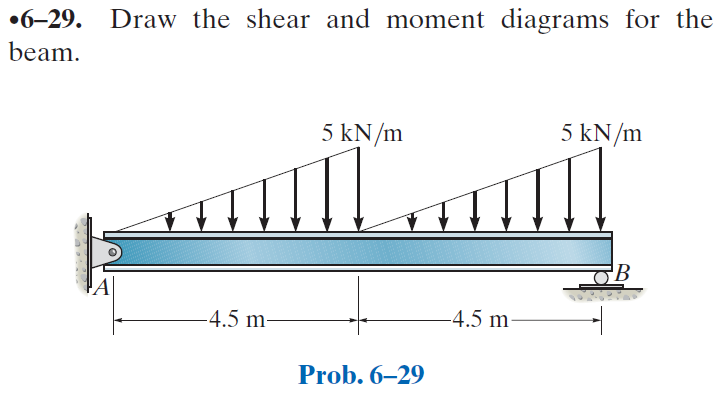

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-29P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-29P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

w1 = findpoly(1, 'thru', [0 0], 'thru', [4.5*u.m -5*u.kN/u.m]);
w2 = findpoly(1, 'thru', [4.5*u.m 0], 'thru', [9*u.m -5*u.kN/u.m]);

# beam

b = beam; 
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 9*u.m);
b = b.add('distributed', 'force', w1, [0 4.5]*u.m);
b = b.add('distributed', 'force', w2, [4.5 9]*u.m, [false true]);
b.L = 9*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(32\,x^{4}-5400\,x^{2}\,m^{2}+260253\,m^{4}\right)}{3456\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq \frac{9}{2}\,m\\ -\frac{\left(x-9\,m\right)\,\left(32\,x^{4}-432\,x^{3}\,m+3672\,x^{2}\,m^{2}-54432\,x\,m^{3}+32805\,m^{4}\right)}{3456\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }\frac{9}{2}\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{160\,x^{4}-16200\,x^{2}\,m^{2}+260253\,m^{4}}{3456\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq \frac{9}{2}\,m\\ -\frac{160\,x^{4}-2880\,x^{3}\,m+22680\,x^{2}\,m^{2}-174960\,x\,m^{3}+522693\,m^{4}}{3456\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }\frac{9}{2}\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{5\,x\,\left(405\,m^{2}-8\,x^{2}\right)}{216}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq \frac{9}{2}\,m\\ -\frac{5\,\left(x-9\,m\right)\,\left(8\,x^{2}-36\,x\,m+243\,m^{2}\right)}{216}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }\frac{9}{2}\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{5\,\left(135\,m^{2}-8\,x^{2}\right)}{72}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq \frac{9}{2}\,m\\ -\frac{5\,\left(8\,x^{2}-72\,x\,m+189\,m^{2}\right)}{72}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }\frac{9}{2}\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{10\,x}{9}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq \frac{9}{2}\,m\\ -\frac{5\,\left(2\,x-9\,m\right)}{9}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }\frac{9}{2}\,m<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 9.375\,\mathrm{kN}\\ \mathrm{Rb} & 13.125\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

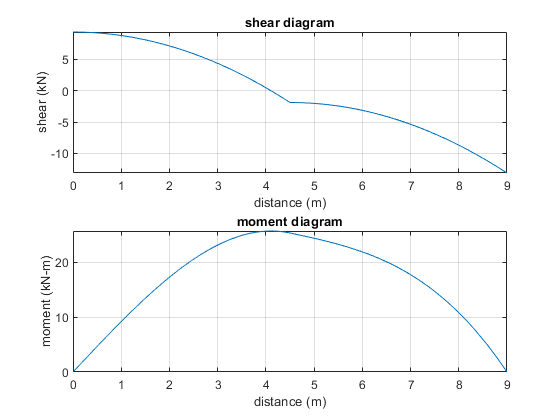

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;